1) Considere um jogo de tabuleiro para crianças muito simples e que envolve 2 jogadores de cada vez. Neste jogo, cada jogador parte da casa 1 e ganha o que chegar mais depressa à casa Meta.

O percurso de cada jogador desde a casa 1 até à casa Meta segue o diagrama a seguir, que indica as casas para onde o jogador se pode mover durante o jogo. A escolha do percurso depende do resultado do lançamento de uma moeda ao ar que não é equilibrada (moeda diferente em cada casa). O resultado do lançamento em cada casa depende de um parâmetro a,, sendo i o número da casa. Nas alíneas seguintes assuma a = (0.2, 0.3, 0.1, 0.45].

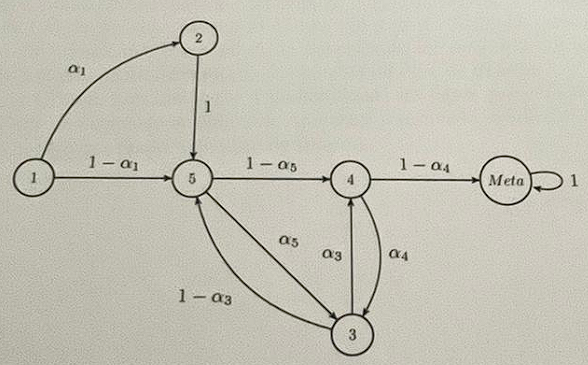

1.a) Represente em Matlab a matriz de transição T, em que Tji representa a probabilidade de o estado j se seguir ao estado i.

a1=0.2;
a3=0.3;
a4=0.1;
a5=0.45;

fprintf("1.a)\n");

1.a)


  %  1      2   3     4       5       6
T = [0      0   0     0       0       0;
     a1     0   0     0       0       0;
     0      0   0     a4      a5      0;
     0      0   a3    0       1-a5    0;
     1-a1   1   1-a3  0       0       0;
     0      0   0     1-a4    0       1;]

T =          0         0         0         0         0         0
    0.2000         0         0         0         0         0
         0         0         0    0.1000    0.4500         0
         0         0    0.3000         0    0.5500         0
    0.8000    1.0000    0.7000         0         0         0
         0         0         0    0.9000         0    1.0000



fprintf("para confirmar:");

para confirmar:

sum(T)

ans =      1     1     1     1     1     1


1.b) Considere o percurso mais pequeno, isto é, o trajeto que passa pelo menor número de casas. Determine a probabilidade do jogador seguir esse percurso para chegar à meta.

fprintf("1.b)\n");

1.b)


fprintf("como começa no estado 1:");

como começa no estado 1:

v = [1 0 0 0 0 0]'

v =      1
     0
     0
     0
     0
     0


fprintf("3 passos até à meta (5,4,M)");

3 passos até à meta (5,4,M)

probabilidade = T^3*v

probabilidade =          0
         0
    0.1340
    0.2180
    0.2520
    0.3960


fprintf("probabilidade de chegar à meta em 3 passos: %f\n",probabilidade(6));

probabilidade de chegar à meta em 3 passos: 0.396000


1.c) Determine o número médio de casas percorridas desde o início até ao fim do jogo (incluindo a casa inicial e a casa final).

fprintf("1.c)\n");

1.c)


% Definição da matriz canônica
FCanonica = T([1 5 3 4 2 6], [1 5 3 4 2 6]);

% Número de estados não absorventes
nena = 5;

% Submatriz Q da forma canônica
Q = FCanonica(1:nena, 1:nena);

% Matriz identidade ajustada ao tamanho de Q
I = eye(length(Q));

% Matriz Fundamental
Fundamental = inv(I - Q);

% Simulação para verificar número médio de passos
N = 1e4;
soma = 0;
for i = 1:N
    seq = crawl(T, 1, 6);
    soma = soma + length(seq);
end

fprintf("Número médio de casas percorridas: %.2f\n", soma / N);

Número médio de casas percorridas: 5.69



% Funções auxiliares

function [state] = crawl(H, first, last)
    % A sequência de estados será salva no vetor "state"
    state = [first]; % Inicialmente contém apenas o estado inicial
    while true
        state(end + 1) = nextState(H, state(end)); % Adiciona o próximo estado
        if state(end) == last % Verifica se alcançou o estado absorvente
            break;
        end
    end
end

function state = nextState(H, currentState)
    % Vetor de probabilidades para o estado atual
    probVector = H(:, currentState)';
    states = 1:length(probVector); % Estados possíveis
    % Gerar próximo estado aleatoriamente de acordo com as probabilidades
    state = discrete_rnd(states, probVector);
end

function state = discrete_rnd(states, probabilities)
    % Gera próximo estado com base nas probabilidades
    r = rand; % Número aleatório entre 0 e 1
    cumulative = cumsum(probabilities); % Probabilidades cumulativas
    state = states(find(r <= cumulative, 1)); % Primeiro estado que corresponde
end